Inicializácia

n0 = 1;%index prveho suboru
n = 6;%pocet suborov


Vykreslenie nameraných dát

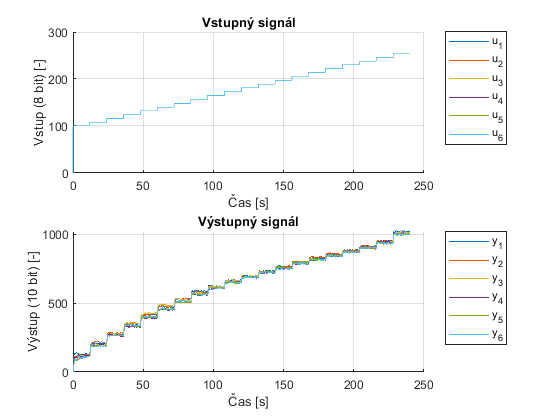

figure;
for i=n0:n0+n-1
    fileName = ['./../dataRepo/allSig_log_prev_mer',num2str(i),'_up.csv'];
    dt = csvread(fileName);
    subplot(2,1,1);
    txt = ['u_',num2str(i)];
    hold on;
    plot(dt(:,1),dt(:,2),'DisplayName',txt);
    hold off;
    subplot(2,1,2);
    txt = ['y_',num2str(i)];
    hold on;
    plot(dt(:,1),dt(:,3),'DisplayName',txt);
    hold off;
end
subplot(2,1,1);
grid on; 
title('Vstupný signál');
legend("Location",'bestoutside');
xlabel('Čas [s]');ylabel('Vstup (8 bit) [-]');
subplot(2,1,2);
grid on; 
title('Výstupný signál');
legend("Location",'bestoutside');
xlabel('Čas [s]');ylabel('Výstup (10 bit) [-]');

Získanie ustálených hodnôt výstupu z nameraných dát

m = 19;%predpoklad pocet derivacii vstupu (zmeny vstupu)
w = 300;%Pocet dat povaz ako ustalene
dataStore = zeros((m+1)*w,n+2);
for i=1:n
    fileName = ['./../dataRepo/allSig_log_prev_mer',num2str((n0-1)+i),'_up.csv'];
    dt = csvread(fileName);
    %dt = dt(2:end,:);
    diffVal = diff(dt(2:end,2));
    ids = find(or(diffVal > 0,diffVal < 0));    
    ln = size(ids,1);
    if ln == m
        ln = size(dt,1);
        id = ids;
        for j=1:m
            if i == 1
                dataStore(1+w*(j-1):w*j,1) = dt(id(j):id(j)+w-1,1);   
                dataStore(1+w*(j-1):w*j,2) = dt(id(j):id(j)+w-1,2); 
            end            
            dataStore(1+w*(j-1):w*j,i+2) = dt(id(j):id(j)+w-1,3);
        end  
    end
end

Vykreslenie získaných ustálených dát

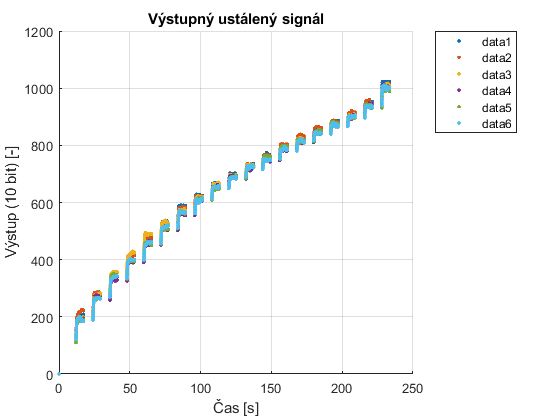

figure;
hold on;
for i=1:n
    plot(dataStore(:,1), dataStore(:,2+i),'.');
end
hold off;
grid on; 
title('Výstupný ustálený signál');
legend("Location",'bestoutside');
xlabel('Čas [s]');ylabel('Výstup (10 bit) [-]');

Určenie dynamiky pracovného bodu

p0 = 206;%Pracovny bod pred Jed. skok
p = 214;%Pracovny bod po Jed. skoku

pIds = find(dataStore(:,2)==p);
pData = dataStore(pIds,:);

pDataMean = zeros(w,3);
pDataMean(:,1:2) = pData(:,1:2);
pomDt = pData(:,3:end)';
pDataMean(:,3) = mean(pomDt);

Vykreslenie

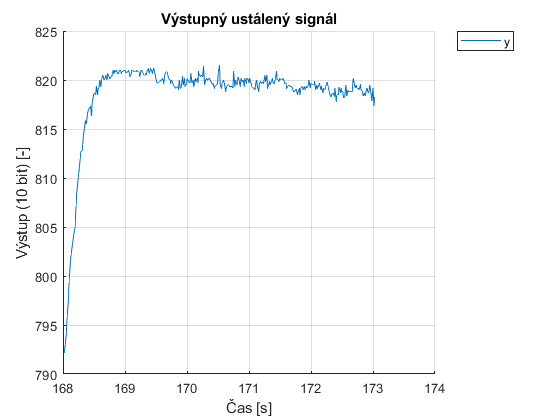

figure;
hold on;
plot(pDataMean(1:end-2,1), pDataMean(1:end-2,3),'DisplayName','y');
hold off;
grid on; 
title('Výstupný ustálený signál');
legend("Location",'bestoutside');
xlabel('Čas [s]');ylabel('Výstup (10 bit) [-]');

Normalizovanie

pDataMean(:,1) = pDataMean(:,1) - pDataMean(1,1);
pDataMean(:,2) = pDataMean(:,2) - p0;
pDataMean(:,3) = pDataMean(:,3) - pDataMean(1,3);

Vykreslenie

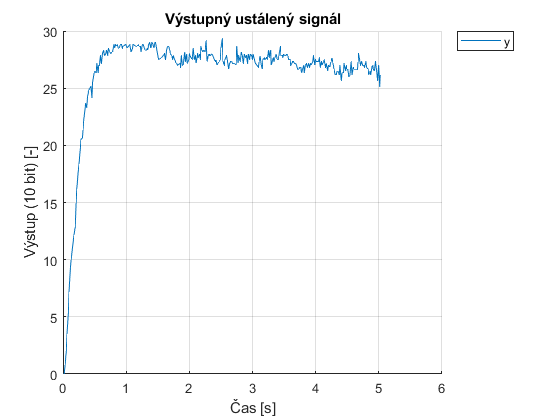

figure;
hold on;
plot(pDataMean(1:end-2,1), pDataMean(1:end-2,3),'DisplayName','y');
hold off;
grid on; 
title('Výstupný ustálený signál');
legend("Location",'bestoutside');
xlabel('Čas [s]');ylabel('Výstup (10 bit) [-]');

Identifikácia

t = pDataMean(1:end-2,1);
u = pDataMean(1:end-2,2);
y = pDataMean(1:end-2,3);

Sústava 1. rádu

y1_v = 0.33*y(end)

y1_v = 8.6350

y2_v = 0.70*y(end)

y2_v = 18.3167


yMean = mean(y(end-100:end));

K = yMean/u(1);

[r,c] = find(y>=y1_v,1,"first");
y1 = y(r,c)

y1 = 9.3333

t1 = t(r,c)

t1 = 0.1180


[r,c] = find(y>=y2_v,1,"first");
y2 = y(r,c)

y2 = 18.3333

t2 = t(r,c)

t2 = 0.2530

s = tf("s");
T = 1.245*(t2-t1)

T = 0.1681

D = 1.498*t1 - 0.498*t2

D = 0.0508

G1_B = (K)/(1+T*s)*exp(-(D*s))

G1_B =
 
                      3.372
  exp(-0.0508*s) * ------------
                   0.1681 s + 1
 
Continuous-time transfer function.



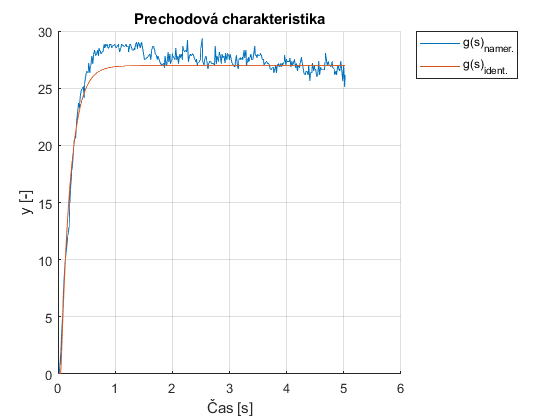

opt = stepDataOptions('InputOffset',0,'StepAmplitude',p-p0);
[st_y,st_t] = step(G1_B,t(end),opt);
figure;
hold on;
plot(t,y,'DisplayName','g(s)_{namer.}');
plot(st_t,st_y,'DisplayName','g(s)_{ident.}');
hold off;
grid on;
xlabel('Čas [s]');
ylabel('y [-]');
title('Prechodová charakteristika');
legend('Location','bestoutside');